# Pregunta 1

clc,clear
tic
beta = 0.96;
sigma = 2; 
pro = 0.84;
r = 0.03; 
w = 1;
A = linspace(0,80,1001);
tol = 1e-2;

Llamamos a nuestra función para calcular la función de valor

[Cti,Ati,Vf,Ap] = valuec(beta,sigma,r,w,A,tol,pro);

Graficamos

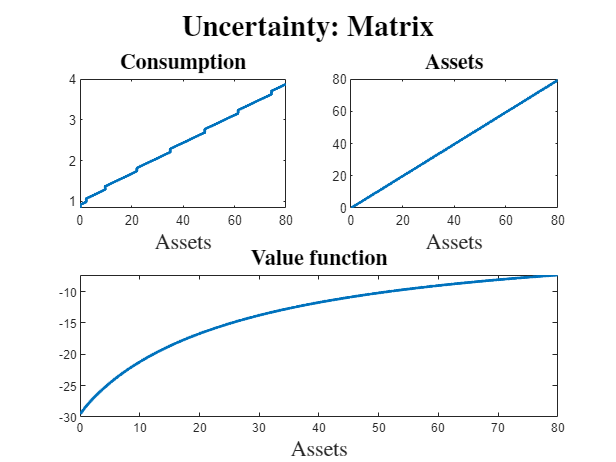

tx= {'Interpreter','Latex','FontSize', 15};
figure;
sgtitle('\textbf{Uncertainty: Matrix}',tx{:},'Fontsize',20)
subplot (2,2,1)
d = plot(A,Cti);
xlabel('Assets',tx{:})
title('\textbf{Consumption}',tx{:})
d(1).LineWidth = 2;
d(length(pro)).LineWidth = 2;

subplot(2,2,2)
p = plot(A,Ati);
xlabel('Assets',tx{:})
title('\textbf{Assets}',tx{:})
p(1).LineWidth = 2;
p(length(pro)).LineWidth = 2;

subplot(2,2,[3,4])
f = plot(A,Vf);
xlabel('Assets',tx{:})
title('\textbf{Value function}',tx{:});
f(1).LineWidth = 2;

toc

Elapsed time is 1.199424 seconds.


# Pregunta 2

Activos

m = 800;
j = 20; 
A_S = zeros(m,1);
A_S(1) = A(j);
for i = 2:m
    pos = find(A==A_S(i-1));
    A_S(i) = Ati(pos);
end

Consumo

C_S = zeros(m,1);
for i = 2:m
    C_S(i) =(1+r)*A_S(i) + pro - A_S(i-1) ; 
end

# Pregunta 3

clc,clear
beta = 0.96;
sigma = 2; 
per_e = 0.97; %persistencia
var_u = 0.13; %varianza
n_e = 5; %numero de estados
r = 0.03; 
w = 1;
A = linspace(0,80,1001);
tol = 1e-2;

Llamamos a la función Discar que nos entregará los 5 posibles estados y la matriz de probabilidad asociada

[pro,tr]= discAR(n_e, per_e,var_u); 

Llamamos a nuestra función para calcular la función de valor

[Cti,Ati,Vf] = value(beta,sigma,r,w,A,tol,pro,tr);

Graficamos

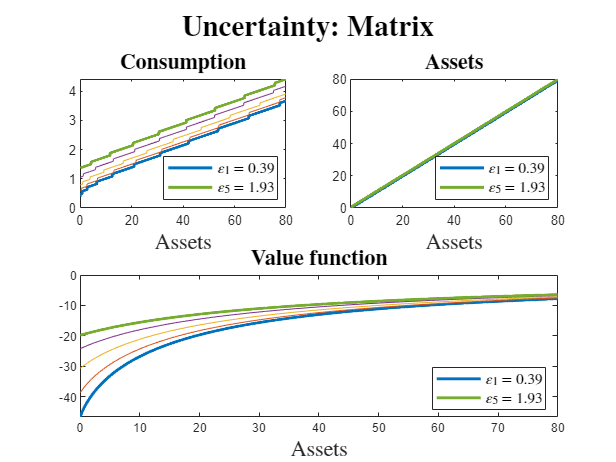

tx= {'Interpreter','Latex','FontSize', 15};

figure;
sgtitle('\textbf{Uncertainty: Matrix}',tx{:},'Fontsize',20)

subplot (2,2,1)
d = plot(A,Cti(:,:));
xlabel('Assets',tx{:})
title('\textbf{Consumption}',tx{:})
legend([d(1),d(length(pro))],'$\varepsilon_1 = 0.39$',...
    '$\varepsilon_5 = 1.93$',tx{:},'fontsize',10,'location','SE'); 
d(1).LineWidth = 2;
d(length(pro)).LineWidth = 2;

subplot(2,2,2)
p = plot(A,Ati(:,:));
xlabel('Assets',tx{:})
title('\textbf{Assets}',tx{:})
legend([p(1),p(length(pro))],'$\varepsilon_1$ = 0.39',...
    '$\varepsilon_5 = 1.93$','location','SE',tx{:},'fontsize',10); 
p(1).LineWidth = 2;
p(length(pro)).LineWidth = 2;

subplot(2,2,[3,4])
f = plot(A,Vf(:,:));
xlabel('Assets',tx{:})
title('\textbf{Value function}',tx{:});
legend([f(1),f(length(pro))],'$\varepsilon_1 = 0.39$',...
    '$\varepsilon_5 = 1.93$',tx{:},'fontsize',10,'location','SE'); 
f(1).LineWidth = 2;
f(length(pro)).LineWidth = 2;